M = 12; %numero elementi antenna 
N = 200; %numero di snapshot 
fc = 3e8; 
A = 1;  
% d = lamba/2; %distanza tra gli elementi dell'antenna 

SigSig = zeros(M, M, N);  
sig = GenSignal(M, fc); 

angles of arrival: 
   -14   -67    68   -44   -50   -88    33    77
     0     0     0     0     0     0     0     0




for ii =1:N 
    x = awgn(sig,10,'measured');
    SigSig(:,:,ii)= x*x'; 
end
Rx = sum(SigSig,3)/N;
[v, lambda] = eig(Rx);

[~,permutation]=sort(diag(lambda), 'descend'); 
lambda = lambda(permutation,permutation);
v=v(:,permutation);

plot(1:M, 20.*log10(abs(lambda)), '*'); 

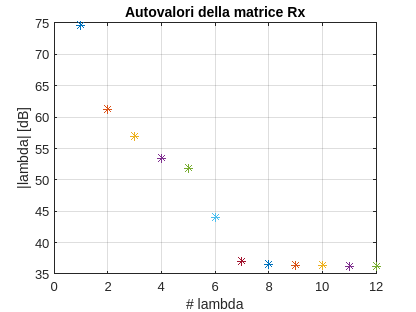

ylabel("|lambda| [dB]");
xlabel("# lambda"); 
title("Autovalori della matrice Rx"); 
grid on; 

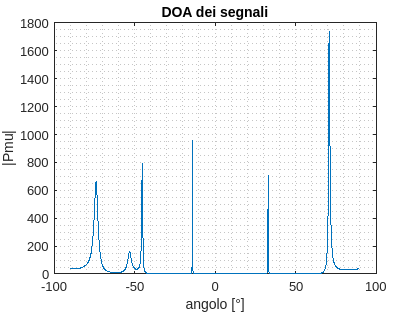

D = input('Insert the number of signals: '); 

lambdaS = lambda(:,1:D);
lambdaN = lambda(:,D+1:M); 

En = v(:, D+1:M); % autovettori del rumore
teta = (-90:0.1:90);
a = exp(-1i*pi*(0:M-1)'*sin((teta(:).')*pi/180)); % nota: 2*pi*d/lambda = pi

Pmu = zeros(1, 1801);

for j=1:length(teta)
    Pmu(j) = inv((a(:, j)'*(En)*En'*a(:,j)));
end

plot(teta, abs(Pmu));
ylabel("|Pmu|"); 
xlabel("angolo [°]"); 
title("DOA dei segnali"); 
grid minor; 